# FDFD 2D Solver for Scattering: Grating Coupler

**Grating couplers** are widely used in photonics to couple light between an optical waveguide and free space or an optical fiber. By simulating the scattering field, this example provides insights into how light interacts with the grating structure, including reflection, transmission, and diffraction.

In this example, we demonstrate the scattering field of a **2D grating coupler**. Wave is injected towards and propagates along the $+x$ direction. The relative permittivity is uniform along $y$ direction, i.e.,  $\varepsilon_r=\varepsilon_r(z,x)$. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

### Step 0: Global settings

The simulation begins by initializing the `Model2D` instance and setting the global parameters. The working plane is defined as the $z-x$** plane**, which aligns with the grating coupler's cross-sectional geometry. The operating wavelength is set to **1.55 µm**, a standard wavelength for optical communications, ensuring the simulation reflects real-world operating conditions.

modelGC = Model2D.initialize();

Model2D: Object Reset and Initialized


modelGC.setLabel('zx'); % work on z-x plane
modelGC.setWavelength(1.55e-6); % work at 1.55 um wavelength

### Step 1: Devcie parameters

#### 1.1 Geometry parameters

The geometry of the grating coupler consists of periodic etches (grating features), a substrate, and an output waveguide. The grating is characterized by its **etch height**, **etch width**, and **period**, with the total grating length determined by the number of etches. The substrate forms the foundation of the device, while the output waveguide is positioned at the end of the grating structure.

h_etch = 0.2e-6; % height (in x-direction) of each grating etch
w_etch = 0.25e-6; % width (in y-direction) of each grating etch
N_etch = 15; % number of grating etches
T_grating = 0.5e-6; % period of gratings (spacing between etches)
total_grating_length = N_etch*T_grating; % total length of grating structure
substrate_height = 0.25e-6; % Height (thickness) of the substrate in x-direction
substrate_length = (N_etch+1)*T_grating-w_etch; % Length of substrate in y-direction
waveguide_length = 4e-6; % Length of the output waveguide in x-direction
waveguide_height = h_etch+substrate_height; % Width of the output waveguide in y-direction
L = substrate_length+waveguide_length; % total length
W = 6e-6; % total width

#### 1.2 Material information

The grating coupler is composed of silicon for the grating and waveguide, and silicon dioxide for the cladding.

eps_GC = 3.4^2; % Si
eps_clad = 1.44^2; % SiO2

### Step 2: Build up simulation device

This step constructs the simulation domain by adding the key components of the grating coupler: the silicon dioxide background, periodic gratings, the grating substrate, and the output waveguide.

#### 2.1 SiO2 background box

The background is modeled as a silicon dioxide rectangle that encompasses the entire simulation domain. This provides a cladding medium for the grating coupler.

modelGC.addDevice(1);
modelGC.setDevice(1).setGeometry('Rectangle', W, L, 'bl', [-2e-6, -waveguide_length]);
modelGC.setDevice(1).setMaterial(eps_clad);

#### 2.2 Gratings

The periodic grating structure is constructed using a loop to place individual grating etches iteratively. Each etch is modeled as a polygon with defined x and y coordinates, using the permittivity of silicon. The loop ensures accurate placement of all etches, including the final one, which adjusts for its partial size. This step also demonstrates the usage of the `'Polygon'` geometry element.

z_g = [0, 0, h_etch, h_etch]+substrate_height;

for ii = 1:N_etch+1
    x_start = (ii-1)*T_grating;
    
    if ii < N_etch
        x_end = x_start+w_etch;
    else
        x_end = x_start+T_grating-w_etch;
    end

    x_g = [x_start, x_end, x_end, x_start];
    
    modelGC.addDevice(ii+1);
    modelGC.setDevice(ii+1).setGeometry('Polygon', z_g, x_g);
    modelGC.setDevice(ii+1).setMaterial(eps_GC);
end

#### 2.3 Grating substrate

The grating substrate, positioned beneath the periodic etches, is modeled as a polygon. This structure supports the grating and is assigned the same permittivity as the grating material.

z_g_substrate = [substrate_height, substrate_height, 0, 0];
x_g_substrate = [0, substrate_length, substrate_length, 0];

modelGC.addDevice(N_etch+3);
modelGC.setDevice(N_etch+3).setGeometry('Polygon', z_g_substrate, x_g_substrate);
modelGC.setDevice(N_etch+3).setMaterial(eps_GC);

#### 2.4 Output waveguide

The output waveguide, placed after the grating structure. It is also modeled as a polygon and assigned the permittivity of silicon.

z_waveguide = [0, 0, h_etch+substrate_height, h_etch+substrate_height];
x_waveguide = [0, -waveguide_length, -waveguide_length, 0];

modelGC.addDevice(N_etch+4);
modelGC.setDevice(N_etch+4).setGeometry('Polygon', z_waveguide, x_waveguide);
modelGC.setDevice(N_etch+4).setMaterial(eps_GC);

#### 2.5 Complete device building

Once all components are added, the device is finalized using `finishDevice`, and a visual representation of the geometry is displayed with `dispImg`.

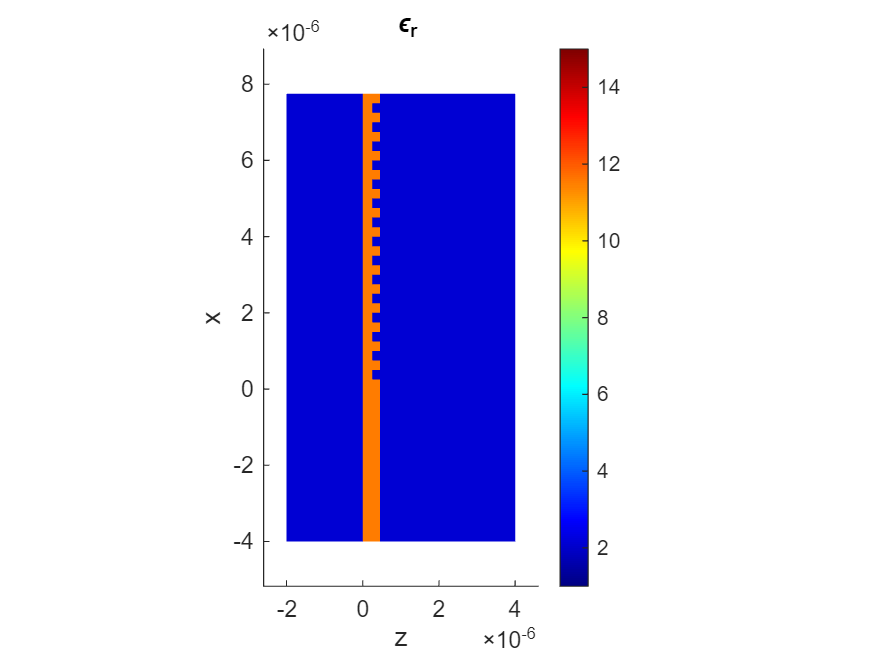

modelGC.assembleDevice;
modelGC.device.dispImg;

### Step 3: FDFD mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

% grid size
dz = 20e-9; % unit: m
dx = 10e-9;

Nz = W/dz;
Nx = L/dx;

% mesh grid
modelGC.setMesh([Nz, Nx], [dz, dx], 'Center', [1e-06, 1.8750e-6]);

### Step 4: Choose FDFD solver

We are going to solve a scattering problem. Therefore, we need to choose `'Scattering' `solver here.

A crucial aspect of the setup involves defining **Perfectly Matched Layers (PML)** around the device. These layers absorb outgoing waves and prevent reflections at the boundaries, ensuring accurate simulation results. The thickness of the PML must be carefully chosen—it should be sufficient to absorb waves effectively but not so thick that it interferes with the device region or reduces the free space available for wave propagation.

pml_thickness = [20, 50];

modelGC.setSolver("Scattering", pml_thickness);

### Step 5: Input port

The port must be defined inside the FDFD region. As mentioned earlier, the input wave propagates along the $-z$ direction. The port is located at $z=3 \mu{\rm m}$ and spans from $x=3 \mu{\rm m}$ to $x=5 \mu{\rm m}$.

modelGC.addPort('-z', 3e-6, [3e-6, 5e-6]);

### Step 6: Gaussian beam input source

A Gaussian beam is used as the input source. The beam parameters include:

- **Waist (**`w0`**)**: The beam's width at its narrowest point, set to $1\mu {\rm m }$.

- **Amplitude (**`amp`**)**: The intensity of the beam, set to 1.

The beam is configured to enter at an angle of **-15°**, simulating an oblique incidence.

w0 = 1e-6; % waist
amp = 1; % amplitude

modelGC.addSource('GaussianBeam', w0, amp);

Source has been set and ready to be used.


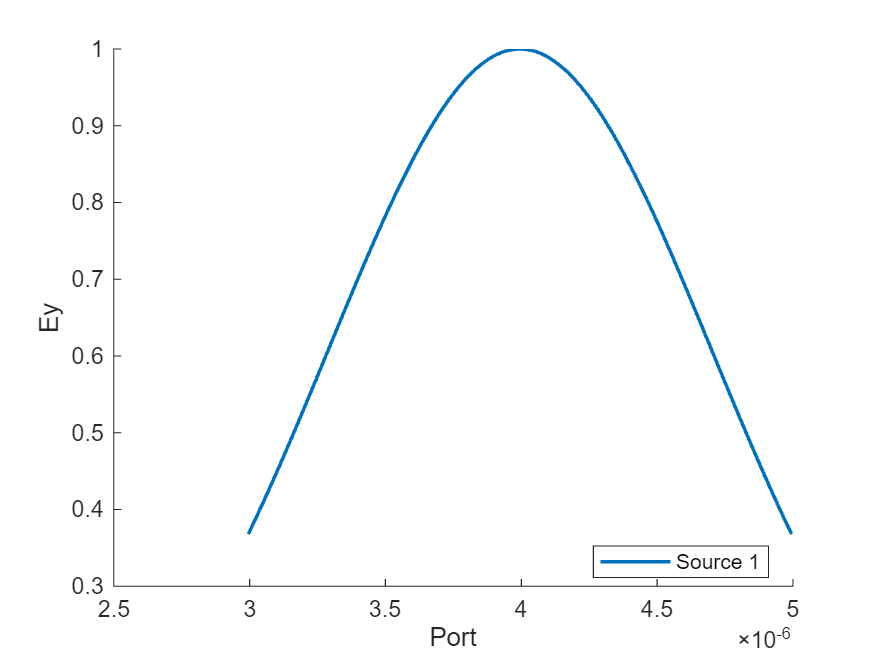

modelGC.setSource.setAngle(-15);
modelGC.source.dispProfile('Ey');

### Step 7: FDFD 2D scattering simulation

To simulate the scattering behavior of the directional coupler, the device must be fully meshed, and the input source properly configured. 

modelGC.solve;

The simulation is executed, and we can export the solution and visualize the scattering field amplitude distribution, $|E_y|$.

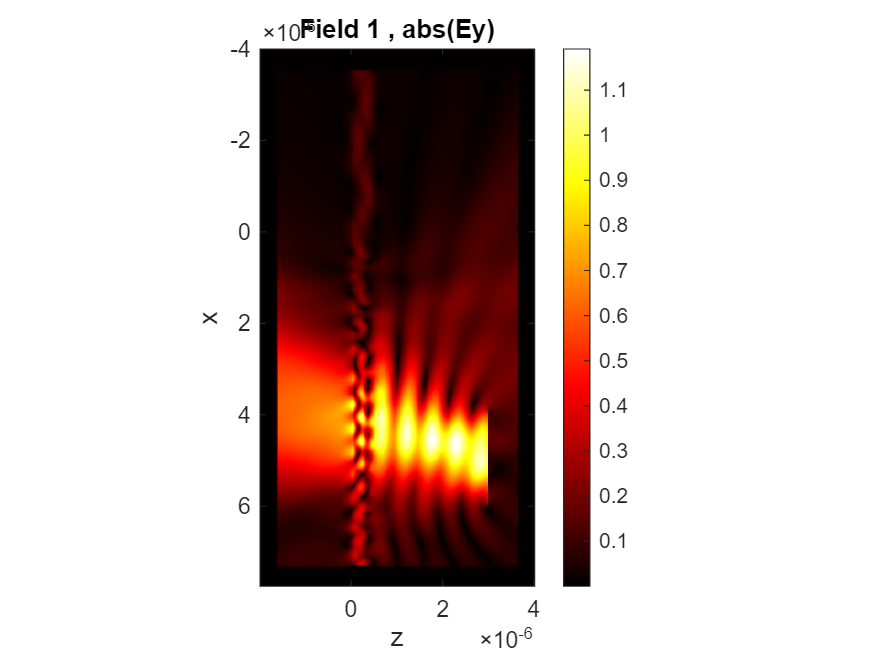

modelGC.dispField('Ey');

solution = modelGC.exportResult;